# Are the Roundworms Alive or Dead?

This example uses transfer learning to train a deep network that can classify images of roundworms as either alive or dead. (Alive worms are round; dead ones are straight.)

## Build a network

Start with a pretrained network

net = alexnet;

Take the CNN layers and add new classification layers at the end.

prebuiltLayers = net.Layers(1:end-3);
layers = [prebuiltLayers;fullyConnectedLayer(2);softmaxLayer;classificationLayer];

## Set some training options.

topts = trainingOptions('adam','InitialLearnRate',0.0001);

## Get the training images and classes

Create a datastore to the images, using a custom read function to preprocess images.

imds = imageDatastore('WormImages');

Get the known classifications from a file and use these as the image labels.

groundtruth = readtable('WormData.csv');
imds.Labels = categorical(groundtruth.Status);

Divide data into training (60%) and testing (40%) sets

[trainImgs,testImgs] = splitEachLabel(imds,0.6,'randomized');

Create augmented image datastores to preprocess the images.

trainds = augmentedImageDatastore([227 227],trainImgs,'ColorPreprocessing','gray2rgb');
testds = augmentedImageDatastore([227 227],testImgs,'ColorPreprocessing','gray2rgb');

## Train the network

wormsnet = trainNetwork(trainds,layers,topts)

Training on single GPU.
Initializing image normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:00 |       57.14% |       0.9193 |      1.0000e-04 |
|      30 |          30 |       00:00:16 |      100.00% |   8.2171e-07 |      1.0000e-04 |
|========================================================================================|


wormsnet =   SeriesNetwork with properties:

    Layers: [25×1 nnet.cnn.layer.Layer]


## Evaluate network on test data

Make predictions

preds = classify(wormsnet,testds);

Compare with reality

truetest = testImgs.Labels;
nnz(preds == truetest)/numel(preds)

ans = 0.9730

View confusion matrix.

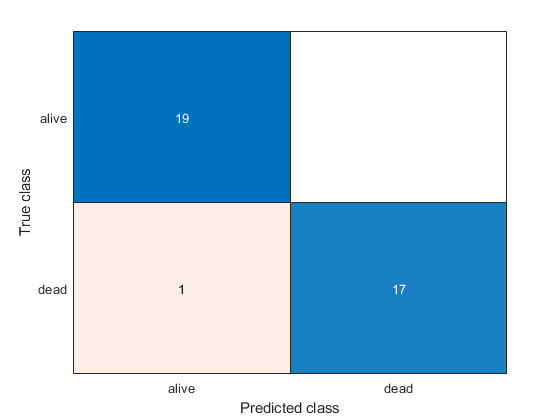

confusionchart(truetest,preds);